# Taller de Simulación Numérica

*F. Pena, P. Quintela*

## Tema 4. El método de diferencias finitas. EDO no lineal evolutiva

 Consideramos el siguiente problema de contorno evolutivo (P):


$$\left\{\begin{array}{ll}
l(x,t)\partial_t\,y(x,t)- \partial^{\,2}_{xx}\,y(x,t) + F(x,t,y,\partial_xy)  = 0,\ x\in[a,b],\ t\in[t_0,t_f],\\
-\partial_x\,y(a,t)+h_ay(a,t)=y_a(t),\\
\partial_x\,y(b,t)+h_by(b,t)=y_b(t),\\
y(x,t_0) = y_0(x).
\end{array}$$


con $F(x,t,y,y') = u(x,t) + v(x,t)y(x,t)^m+w(x,t)y(x,t)'$. Por comodidad, omitiremos la dependencia en $x,t$.

### Discretización en tiempo

Tomamos una discretización de $[t_0,t_f]$ en $n_t$ intervalos con paso $\Delta t = \frac{t_f-t_0}{n_t}$ y tiempos $t^j=t_0+j\Delta t,\ j\in\{0,\ldots,n_t\}$, para obtener el problema (Ph):


$$\left\{\begin{array}{ll}
l^j\frac{y^j-y^{j-1}}{\Delta t}- \partial^{\,2}_{xx}\,y^j + F(x,t_j,y^j,(y^j)')  = 0,\ x\in[a,b],\ j\in\{1,\ldots,n_t\},\\
-(y^j)'(a)+h_ay^j(a)=y_{a}^j,\\
(y^j)'(b)+h_by^j(b)=y_{b}^j,\\
y^0 = y_0.
\end{array}$$


donde, para cada campo $f(x,t)$, denotamos $f^j = f(\cdot,t_j)$. 

### Caso lineal

Usando la expresión lineal de $F$ ($m=1$) y reordenando términos:

$\partial^{\,2}_{xx}\,y^j = u^j - \frac{l^jy^{j-1}}{\Delta t} + \left(v^j+\frac{l^j}{\Delta t}\right)y^j + w^j\partial_x\,y^j$.

Si definimos $\tilde{u}^j = u^j-\frac{l^jy^{j-1}}{\Delta t}$, $\tilde{v}^j = v^j+\frac{l^j}{\Delta t}$ entonces es una EDO lineal.

#### Discretización en espacio

Tomamos una discretización de $[a,b]$ en $n_x$ intervalos con paso $h = \frac{b-a}{n_x}$ y puntos $x_i=a+ih,\ i\in\{0,\ldots,n_x\}$:

$\frac{y^j_{i+1}-2y^j_i+y^j_{i-1}}{h^2} = u_i^j - \frac{l_i^jy^{j-1}_i}{\Delta t} + \left(v_i^j+\frac{l_i^j}{\Delta t}\right)y_i^j + w_i^j\frac{y^j_{i+1}-y^j_{i-1}}{2h}$.

#### Buen planteamiento del problema discreto

Por comodidad, omitiremos el superíndice $j$, aunque manteniendo el del paso anterior en $y^{j-1}$. 

Para cada $i\in\{1,\ldots,n_x-1\}$ la fila $i$-ésima de la matriz es $a_i\,y_{i-1}+ b_i\, y_i+c_i\,y_{i+1}=-h^2\left(u_i-\frac{l_iy_i^{j-1}}{\Delta t}\right)$, con:

 
$$\begin{array}{rcrcl}
a_i &=& -1&-&\frac{h}{2}w_i\,, \\

d_i &=& 2 &+&h^2\left(v_i+\frac{l_i}{\Delta t}\right), \\ 

c_i &=& -1&+&\frac{h}{2}w_i\,.
\end{array}$$


Si $v>0$, $l>0$, entonces $|d_i|>2$. Para que la matriz sea estrictamente diagonal dominante, basta pedir que $\left|\frac h2 w_i\right|<1$. En la práctica, basta tomar $h < \frac 2M_w$, con $M_w = \max_{(x,t)\in[a,b]\times[t_0,t_f]}|w(x,t)|$.

#### Estabilidad de la discretización

Para garantizar que la evolución temporal está bien considerada, el término en $d_i$ proveniente de la derivada temporal debe ser mayor que los asociados a la variación espacial:

$\frac{l_i}{\Delta t} > \frac{2}{h^2} + v_i$. 

En la práctica, basta tomar $\frac{m_l}{\Delta t} > \frac{2}{h^2}+M_v$, es decir, $\Delta t < \frac{m_l}{M_v+2/h^2}$ siendo $m_i$ y $M_v$ el mínimo de $l$ y el máximo de $v$, respectivamente. 

En particular, si  $h$ es muy pequeño, obliga a que $\Delta t$ también lo sea.

### Implementación del algoritmo

La función [`dfnle`](matlab:open('./dfnle.m')) debe implementar el cálculo de la solución del problema evolutivo. Sus argumentos de entrada son:

- La estructura `F,` con cuatro funciones anónimas `l(x,t)`, `u(x,t)`, `v(x,t)`, `w(x,t)` con argumentos los vectores `x`, `t` de puntos y tiempos de discretización, respectivamente y el exponente `m` (para que nos sirva en el caso no lineal).

- La estructura `bi,` que define las condiciones de contorno y la condición inicial. Tiene los mismos atributos que la estructura `bc` de la práctica anterior, salvo:

                  Las funciones anónimas `bi.ya(t)` y `bi.yb(t)` con argumento el vector `t` de tiempos de discretización.

                  El intervalo temporal `[bi.t0, bi.tf]`.

                  La condición inicial `bi.y0` es una función anónima que depende de `x`.

- El número de pasos espaciales, `nx`.

- El número de pasos temporales, `nt`.

El resultado es:

- El vector de puntos de discretización, `x`, 

- El vector de tiempos de discretización, t, 

- La matriz de valores de la solución aproximada en los puntos anteriores, Y, de dimension `length(t)` $\times$ `length(x)`. 

Para cada paso de tiempo $j$, salvo el inicial, se deben crear dos estructuras `Fs` y `bc`, para la $F$ estacionaria y sus condiciones de contorno, llamar a `df` y guardar la solución en la $j$-ésima fila de $Y$.

### Ejercicio 4.1. Test académico, caso lineal

- **Diseña un problema evolutivo lineal.**

Diseña un problema (P) con solución exacta $y=t\mathrm{e}^x$ con $(x,t) \in [0,2]\times [1,5]$ y que cumpla las restricciones impuestas para el problema lineal discreto ($v>0$, $l>0$).

Solución:

La EDO $\partial_t\,y- \partial^{\,2}_{xx}\,y + u + v y + w y'= 0$ para $y=t\mathrm{e}^x$ queda $(1-t)\mathrm{e}^x + u + (v +w) t\mathrm{e}^x = 0$. Tomamos $v = \frac{1}{t}$, $w=t$ y, en consecuencia, $u = (-t^2+t-2)\mathrm{e}^x$.

La condición $-\partial_x\,y(0,t)+h_ay(0,t)=y_a(t)$ queda $-t+h_at=y_a(t)$. Tomamos $h_a=1$ y, en consecuencia, $y_a = 0$.

La condición $\partial_x\,y(2,t)+h_by(2,t)=y_b(t)$ queda $t\mathrm{e}^2+h_bt\mathrm{e}^2=y_b(t)$. Tomamos $h_b=2
$ y, en consecuencia, $y_bn = 3t\mathrm{e}^2$.

La condición inicial es $y_0=\mathrm{e}^x$.

- **Para el error relativo, calcula la norma **$L^{\infty}([a,b]\times[t_0,t_f])$ **discreta y representa gráficamenta la norma **$L^\infty(a,b)$ **discreta frente al tiempo.**

Crea una función `check` que compruebe si $h < \frac 2M_w$ y $\Delta t < \frac{m_l}{M_v+2/h^2}$.

%Solucion
clear all

sol = @(x,t) t.*exp(x);

F  = struct('l', @(x,t)  ones(size(x)), ...
    'u', @(x,t)  exp(x).*(-t.^2+t-2), ...
    'v', @(x,t)  (ones(size(x)))./t, ...
    'w', @(x,t)  ones(size(x)).*t, ...
    'm', 1);
bi = struct('blk_a', false, 'a', 0, 'ya', @(t) 0,          'ha', 1, ...
    'blk_b', false, 'b', 2, 'yb', @(t) 3*t*exp(2), 'hb', 2, ...
    't0', 1,...
    'tf', 5, ...
    'y0', @(x) exp(x), ...
    'hx', 0.2, ...
    'dt', 1);

nx = (bi.b-bi.a)/bi.hx;
nt = (bi.tf-bi.t0)/bi.dt;

nl = struct('yk', exp(bi.a  +  bi.hx*(0:nx)), 'maxit', 100, 'tol', 1.e-6);

check(F,bi);

Cumple la estabilidad de la discretización. Retirar punto y coma para saber el DeltaT máximo.


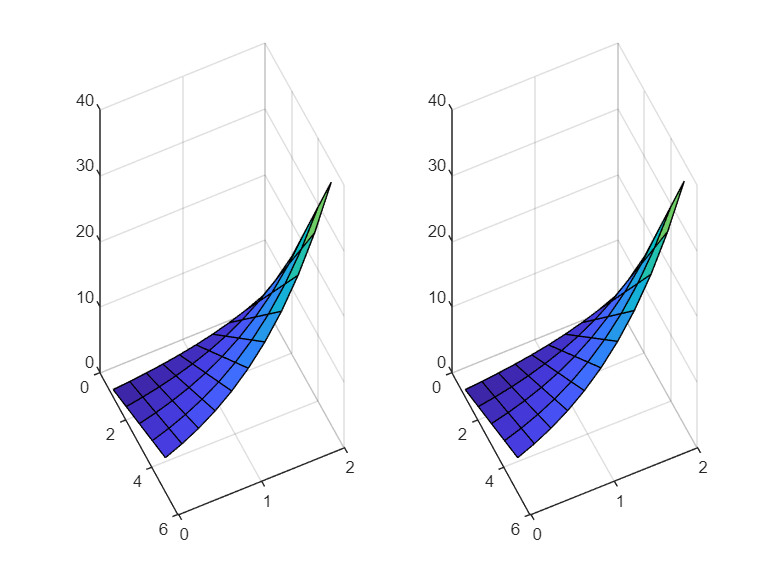

[x, t, Y] = dfnle_esquema(F, bi, nx, nt, nl, @df);

clf
tiledlayout(1,2)
nexttile
surf(t,x,transpose(Y))
view([64.7 30.8])
hold on
clear Z
for i=1:length(x)
    for j=1:length(t)
        Z(i,j)=sol(x(i),t(j));
    end
end
nexttile
surf(t,x,Z)
view([64.7 30.8])

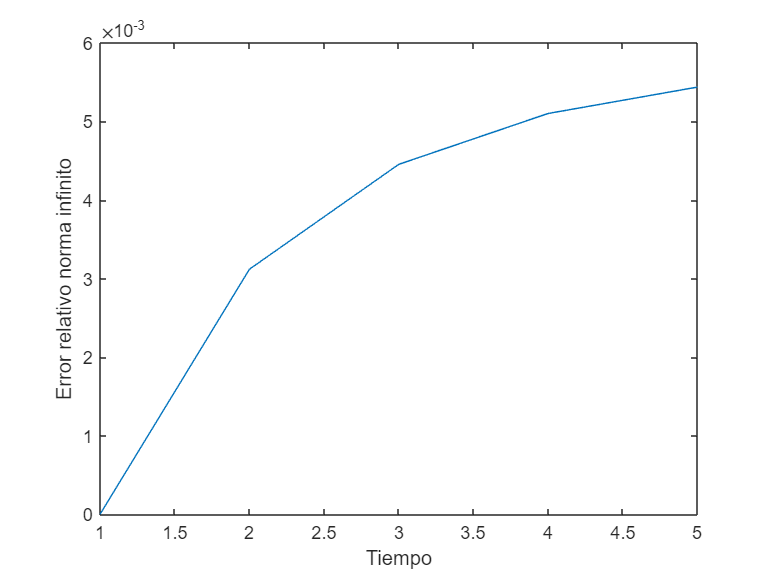

ErrRel = abs(Z-transpose(Y))./Z;

tiledlayout('flow')
plot(t,max(ErrRel))
xlabel('Tiempo')
ylabel('Error relativo norma infinito')

- **Calcula las normas **$L^{\infty}(t_0,t_f; L_2(a,b))$ **y **$L^{\infty}(t_0,t_f; H^1(a,b))$ **discretas para el error absoluto.**

Crea una función `normInft` que devuelva ambas cantidades. Utiliza que [`trapz(..., 2)`](http://trapz%28...%2C2%29https//es.mathworks.com/help/matlab/ref/trapz.html) integra a lo largo de las columnas de una matriz (su dimension 2).

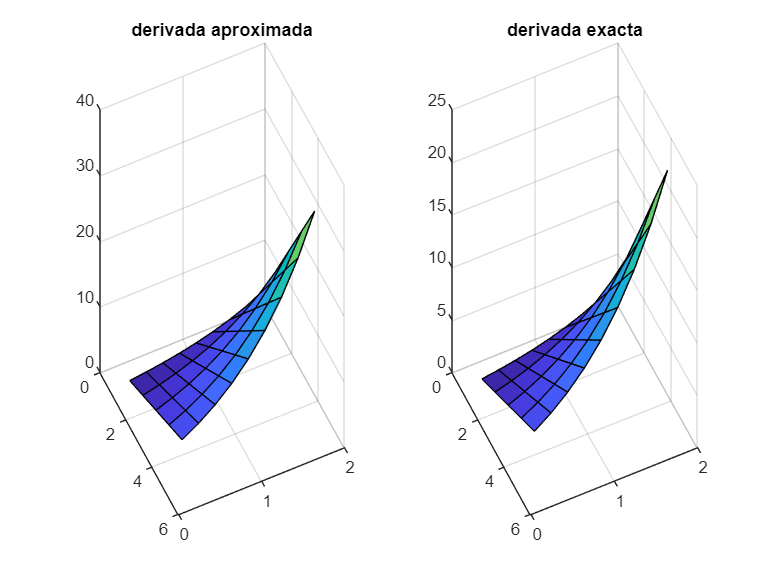

clf
err = abs(transpose(Y)-Z);
[nL2, nH1] = normaInft(x,t,Y,sol)

### Ejercicio 4.2. Balance de masa de un reactor químico

Considera el problema evolutivo:


$$\left\{\begin{array}{l}
\frac{1}{D}\partial_t\,c-\partial^{\,2}_{xx}c+\frac{\gamma}{D} c^m+ \frac{U}{D}\partial_xc=0 ,\ x\in[0,L],\ t\in[t_0,t_f]\\
 -\partial_x\,c(0,t) +\frac{U}{D}c(0,t)= \frac{U}{D}c_{in} ,\\
\partial_x\,c(L,t) = 0\,,\\
c(\cdot,t_0) = 0.
\end{array}$$


- **Resuelve el problema anterior** **con decaimiento lineal** ($m=1$) **mediante diferencias finitas.** 

Usa los siguientes datos: $L=10\, \text{m}$, $[t_0, t_f] = [0, 25]\,\mathrm{h}$,$D=2\,\text{m}^2/\text{h}$, $U=2\,\text{m}/\text{h}$, $\gamma=0.2$, $c_{in}=100\,\text{mol}/\text{m}^3$ y $h = 0.25\,\mathrm{m}$. Representa la solución con [contourf](https://es.mathworks.com/help/matlab/ref/contourf.html). 

%Solucion
L = 10; D = 2; U = 2; gm = 0.2; cin = 100;
m = 1;

F.l = @(x,t) zeros(size(x));
[x, t, Y] = dfnle_esquema(F, bi, nx, nt, nl, @df);
solEst = Y(2,:);

F  = struct('l', @(x,t)  1/D.*ones(size(x)), ...
    'u', @(x,t)   zeros(size(x)), ...
    'v', @(x,t) gm*(ones(size(x))).^m/D, ...
    'w', @(x,t)  U*ones(size(x))/D, ...
    'm', m);
bi = struct('blk_a', false, 'a', 0, 'ya', @(t) U/D,          'ha', U/D, ...
    'blk_b', false, 'b', L, 'yb', @(t) 0, 'hb', 0, ...
    't0', 0,...
    'tf', 25, ...
    'y0', @(x) 0, ...
    'hx', 0.25, ...
    'dt', 0.25);

nx = (bi.b-bi.a)/bi.hx;
nt = (bi.tf-bi.t0)/bi.dt;

nl = struct('yk', ones(1,nx+1), 'maxit', 100, 'tol', 1.e-6);

check(F,bi);

Cumple la estabilidad de la discretización. Retirar punto y coma para saber el DeltaT máximo.


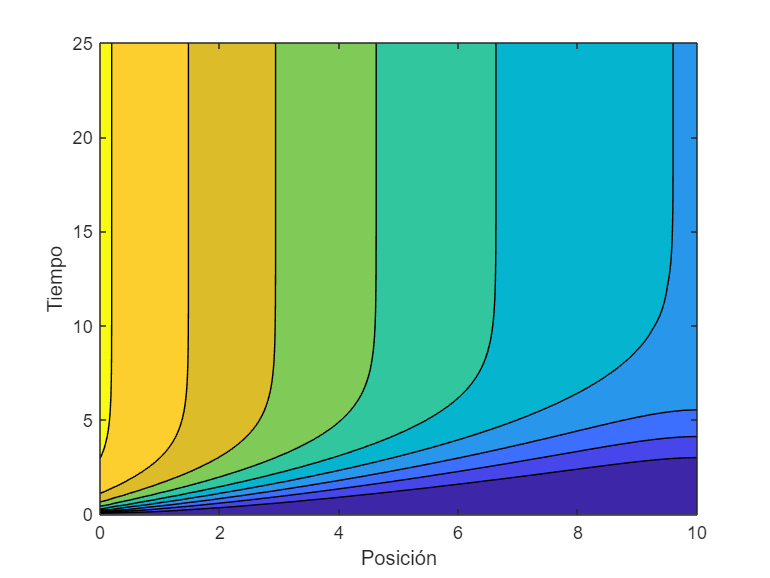

[x, t, Y] = dfnle_esquema(F, bi, nx, nt, nl, @df);
clf
contourf(x,t,Y)
ylabel('Tiempo')
xlabel('Posición')

**Nota para la clase:** La limitación sobre $\Delta t$ suele ser la más exigente. Se puede tener una función que calcule, dado $h$, el $\Delta t$ máximo que se puede tomar:

**Lo hemos implementado en la función** *check*.

check(F,bi)

Cumple la estabilidad de la discretización. Retirar punto y coma para saber el DeltaT máximo.


ans = 0.0156

- **Representa gráficamente la solución aproximada para **$t\in\{0.25, 2.5, 7.5, 25\}\,\mathrm{h}$ **e incluye la gráfica de la exacta del problema estacionario.** 

Usa la solución aproximada del apartado anterior. 

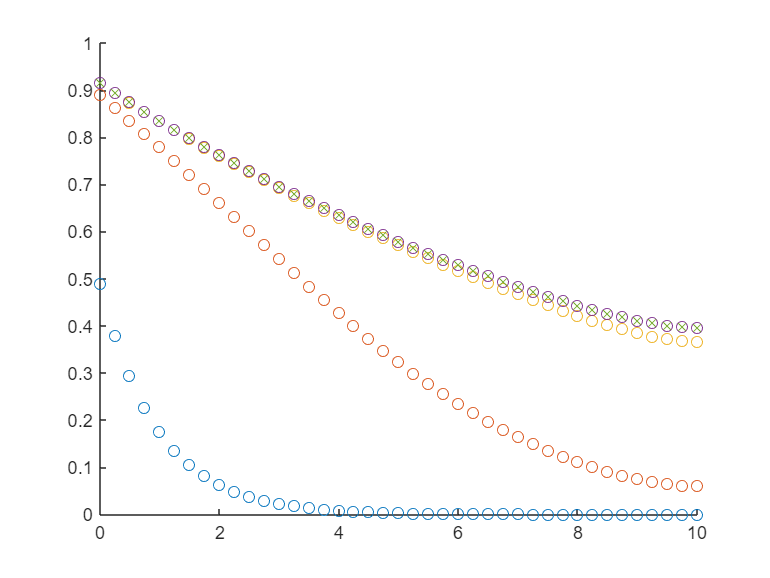

%Solucion
clf
hold on
for i = [0.25, 2.5, 7.5, 25]
    plot(x,Y(find(t==i),:),'o')
end

plot(x,solEst,'x')
hold off

**Notas para la clase:** Se ha comprobado que la Figura B5.3a de la página 144 de [Caldwell](http://www.math.utah.edu/~cherk/teach/5740MathModeling/12mathmodel/sources/Caldwell%20&%20Ng%202004%20Mathematical%20Modelling.Case%20Studies%20&%20Projects.pdf), que debería coincidir con la gráfica pedida, es errónea.

- **Comprueba la conservación numérica de la masa, representando gráficamente la norma **$L^\infty(0,L)$** discreta del residuo de la EDO frente al tiempo.**

Adapta las fórmulas de derivación numérica para matrices, tal y como se hizo para el cálculo de la norma $L^\infty(t_0,t_f;H^1(0,L))$.

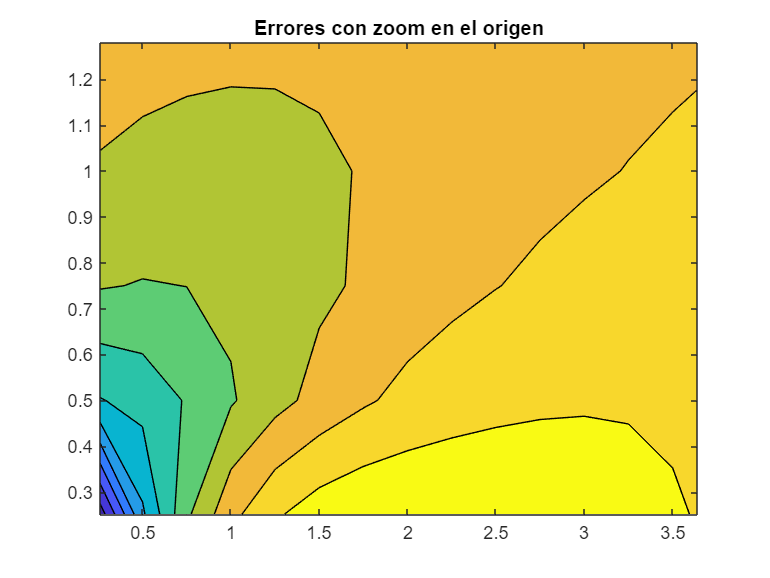

Ya = Y(2:end-1,2:end-1);

d1x = @(Y,h) (Y(:,3:end)-Y(:,1:end-2))./(2.*h);            %aprox. primera derivada espacial
Y1xa = d1x(Y,bi.hx);

d2x = @(Y,h) (Y(:,3:end)-2.*Y(:,2:end-1)+Y(:,1:end-2))./h^2;     %aprox. segunda derivada espacial
Y2xa = d2x(Y,bi.hx);

d1t = @(Y,dt) (Y(3:end,:)-Y(1:end-2,:))./(2.*dt);            %aprox. primera derivada temporal
Y1ta = d1t(Y,bi.dt);

% Ajustamos dimensionalmente:
Y1xa = Y1xa(2:end-1,:);
Y2xa = Y2xa(2:end-1,:);
Y1ta = Y1ta(:,2:end-1);
xr = x(2:end-1);
tr = t(2:end-1);

res = F.l(xr,tr).*Y1ta - Y2xa + F.u(xr,tr) + F.v(xr,tr).*Ya + F.w(xr,tr).*Y1xa;
contourf(xr,tr,res)

xlim([0.26 3.64])
ylim([0.252 1.279])
title('Errores con zoom en el origen')

### Caso no lineal, algoritmo de iteración funcional

Usando la expresión no lineal de $F$ en ($\text{P}_h$) y reordenando términos:

$\partial^{\,2}_{xx}\,y = u - \frac{ly^{j-1}}{\Delta t} + \left(vy^{m-1}+\frac{l}{\Delta t}\right)y + w\partial_x\,y$.

Hemos ocultado el superíndice $j$ salvo para la solución del tiempo anterior$y^{j-1}$. Observa que $y^{m-1}$ es simplemente una potencia.

### Algoritmo de iteración funcional

Para cada tiempo $t^j$, se debe obtener un punto fijo del operador $\mathcal{F}:y_k\in\mathcal{C}^2([a,b])\mapsto y\in\mathcal{C}^2([a,b])$ definido por:

    $y=\mathcal{F}(y_k)$* es la solución de *$\partial^{\,2}_{xx}\,y = u - \frac{ly^{j-1}}{\Delta t} + \left(vy_k^{m-1}+\frac{l}{\Delta t}\right)y + w\partial_x\,y$ *cumpliendo las condiciones de contorno de *($\text{P}$)*.*

El paso $k$ del algoritmo de iteración funcional consiste en:

- Sea $y_k\in\mathcal{C}^2([a,b])$ dado.

- Se calcula $y_{k+1}=\mathcal{F}(y_k)$.

- Si $\|y_{k+1}-y_k\|<\varepsilon$ hay convergencia; si no, sigue iterando.

Podemos definir $\tilde{u} = u-\frac{ly^{j-1}}{\Delta t}$ antes de la llamada a iteración funcional. Sin embargo, esto no es posible para $\tilde{v} = vy_k^{m-1}+\frac{l}{\Delta t}$, pues $y_k$ depende del bucle de iteración funcional. Por tanto, $\frac{l}{\Delta t}$ debe incorporarse a $\tilde{v}$ **dentro** de [`dfif`](matlab:open('./dfif.m')).

### Implementación del algoritmo

La función [`dfnle`](matlab:open('./dfnle.m')) del anterior caso lineal debe modificarse para incorporar dos argumentos de entrada adicionales:

- La estructura `nl,` que define el maximo de iteraciones `maxit`, y la tolerancia `tol`. En el caso evolutivo no es necesario incluir el iterante inicial `yk`, pues se suele tomar la solución en el tiempo anterior.

- El manejador de función ([function handle](https://es.mathworks.com/help/matlab/function-handles.html)) `algor` con la función de iteración funcional, `@dfif`.

Para cada paso de tiempo $j$, salvo el inicial, se deben crear dos estructuras `Fs` y `bc`, para la $F$ estacionaria y sus condiciones de contorno, llamar a `algor` y guardar la solcuión en al $j$-ésima fila de $Y$. 

A diferencia del caso lineal, `Fs` debe contener:

- La función anónima `v` con la evaluación en tiempo de la función $v$ **original**.

- La función anónima `lt` con la evaluación en tiempo de $\frac{l}{\Delta t}$, para ser sumada dentro de `dfif`.

La función [dfif](matlab:open('./dfif.m')) debe modificarse de forma que la nueva versión sirva también para la práctica anterior. En particular, debe:

- Incorporar en la función `viF` el término $\frac{l}{\Delta t}$ si `F` tiene el campo `lt`. Esto se puede comprobar con el comando [isfield](https://es.mathworks.com/help/matlab/ref/isfield.html)).

- Por simplicidad, eliminar la parte del residuo del test de convergencia en el caso evolutivo (es decir, cuando exista el campo `lt)`.

### Ejercicio 4.3. Test académico para iteración funcional

- **Diseña un problema evolutivo no lineal.**

Diseña un problema no lineal basado en el problema del Ejercicio 4.1.

Solución:

La EDO $\partial_t\,y- \partial^{\,2}_{xx}\,y + u + v y^m + w y'= 0$ para $y=t\mathrm{e}^x$ queda $(1-t)\mathrm{e}^x + u + vt^m\mathrm{e}^{mx} + w t\mathrm{e}^x = 0$. Tomamos $v = \frac{1}{t}$, $w=t$ y, en consecuencia, $u = (-t^2+t-1)\mathrm{e}^x-t^{m-1}\mathrm{e}^{mx}$.

La condición $-\partial_x\,y(0,t)+h_ay(0,t)=y_a(t)$ queda $-t=y_a(t)-h_at$. Tomamos $h_a=1$ y, en consecuencia, $y_a = 0$.

Tomamos una condición Dirichlet en $x=b$, $y_b(t) = t\mathrm{e}^2$.

La condición inicial es $y_0=\mathrm{e}^x$.

- **Para el error relativo, calcula la norma **$L^{\infty}([a,b]\times[t_0,t_f])$**y representa gráficamente la norma **$L^\infty(a,b)$**frente al tiempo.**

%Solucion
clear all
sol = @(x,t) t.*exp(x);
m=2;
F  = struct('l', @(x,t)  ones(size(x)), ...
    'u', @(x,t)  exp(x).*(-t.^2+t-1)-t.^(m-1).*exp(m.*x), ...
    'v', @(x,t)  (ones(size(x)))./t, ...
    'w', @(x,t)  ones(size(x))*t, ...
    'm', 2);
bi = struct('blk_a', false, 'a', 0, 'ya', @(t) 0,          'ha', 1, ...
    'blk_b', true, 'b', 2, 'yb', @(t) t*exp(2), 'hb', 2, ...
    't0', 1,...
    'tf', 5, ...
    'y0', @(x) exp(x), ...
    'hx', 0.2, ...
    'dt', 1);

hx = 0.05;
nx = (bi.b-bi.a)/hx;
x  =  bi.a  +  hx*(0:nx);
nl = struct('yk', exp(x), 'maxit', 1500, 'tol', 1.e-4);

nt = (bi.tf-bi.t0)/bi.dt;

check(F,bi)

Cumple la estabilidad de la discretización. Retirar punto y coma para saber el DeltaT máximo.


ans = 0.0208

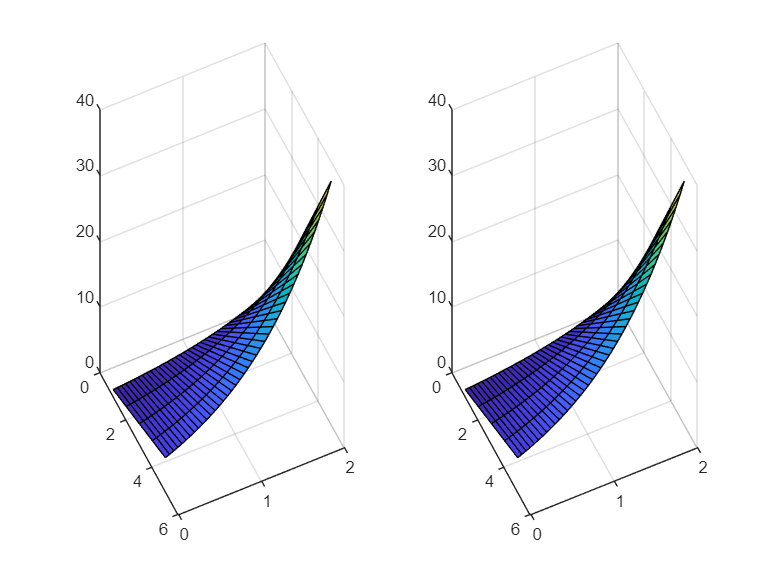

[x, t, Y] = dfnle_esquema(F, bi, nx, nt, nl, @dfif);
clf
tiledlayout(1,2)
nexttile
surf(t,x,transpose(Y))
view([64.7 30.8])
hold on
clear Z
for i=1:length(x)
    for j=1:length(t)
        Z(i,j)=sol(x(i),t(j));
    end
end
nexttile
surf(t,x,Z)
view([64.7 30.8])

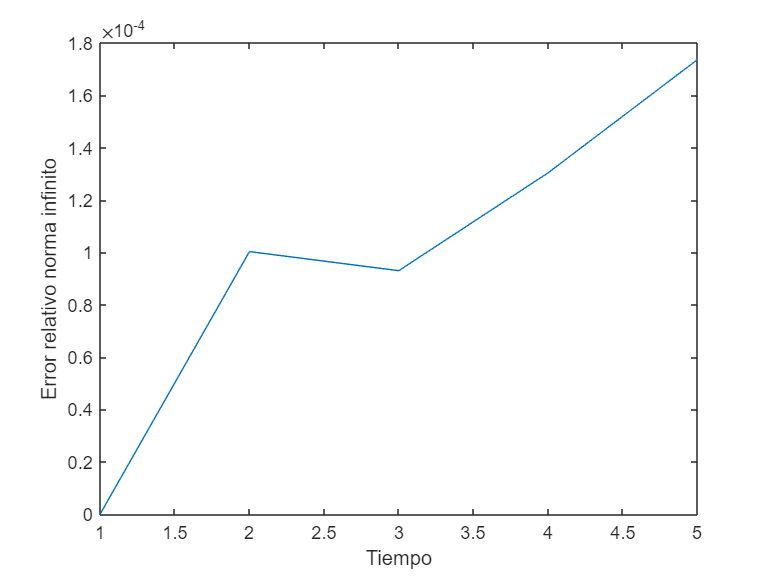

ErrRel = abs(Z-transpose(Y))./Z;
tiledlayout('flow')
plot(t,max(ErrRel))
xlabel('Tiempo')
ylabel('Error relativo norma infinito')

### Ejercicio 4.4. Balance de masa de un reactor no lineal (iteración funcional)

Considera el problema del Ejercicio 4.2.

- **Resuelve el problema no lineal con **$m=2$ **mediante diferencias finitas.** 

Usa los siguientes datos: $L=10\, \text{m}$, $D=1\,\text{m}^2/\text{h}$, $U=1\,\text{m}/\text{h}$, $\gamma=0.2$, $c_{in}=100\,\text{mol}/\text{m}^3$ y un paso $\Delta x = 0.25\,\text{m}$.  Representa la solución con [contourf](https://es.mathworks.com/help/matlab/ref/contourf.html). 

%Solucion
L = 10; D = 1; U = 1; gm = 0.2; cin = 100;
m = 2;
F  = struct('l', @(x,t)  1/D.*ones(size(x)), ...
    'u', @(x,t)   zeros(size(x)), ...
    'v', @(x,t) gm*(ones(size(x))).^m/D, ...
    'w', @(x,t)  U*ones(size(x))/D, ...
    'm', m);
bi = struct('blk_a', false, 'a', 0, 'ya', @(t) U/D,          'ha', U/D, ...
    'blk_b', false, 'b', L, 'yb', @(t) 0, 'hb', 0, ...
    't0', 0,...
    'tf', 25, ...
    'y0', @(x) 0, ...
    'hx', 0.25, ...
    'dt', 0.25);

nx = (bi.b-bi.a)/bi.hx;
nt = (bi.tf-bi.t0)/bi.dt;

nl = struct('yk', ones(1,nx+1), 'maxit', 100, 'tol', 1.e-6);


check(F,bi)

Cumple la estabilidad de la discretización. Retirar punto y coma para saber el DeltaT máximo.


ans = 0.0313

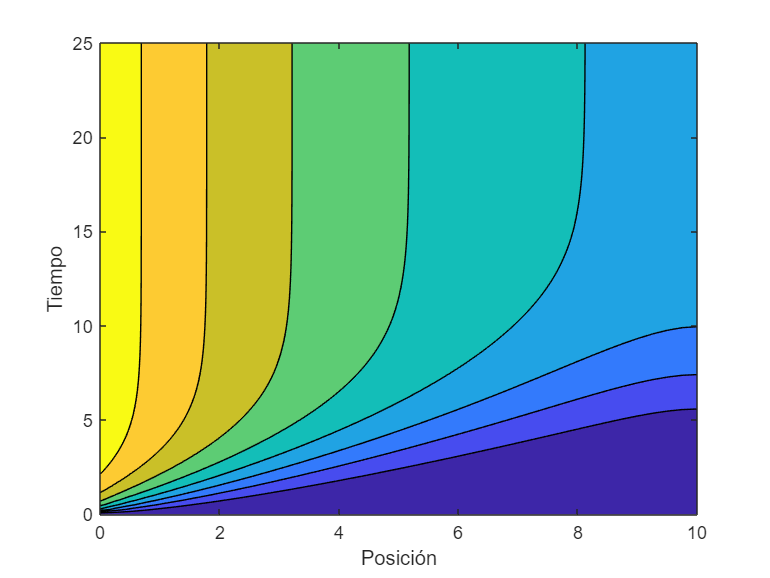

[x, t, Y] = dfnle_esquema(F, bi, nx, nt, nl, @dfif);

clf
contourf(x,t,Y)
ylabel('Tiempo')
xlabel('Posición')

### Algoritmo de Newton

Partimos de la expresión no lineal de $F$ en ($\text{P}_h$):

$\partial^{\,2}_{xx}\,y = u - \frac{ly^{j-1}}{\Delta t} + \left(vy^{m-1}+\frac{l}{\Delta t}\right)y + w\partial_x\,y$.

Hemos ocultado el superíndice $j$ salvo para la solución del tiempo anterior$y^{j-1}$. Observa que $y^{m-1}$ es simplemente una potencia.

Para cada tiempo $t^j$, se debe obtener una raíz del operador $\mathcal{G}:y\in\mathcal{C}_{bc}^2([a,b])\mapsto r\in\mathcal{C}([a,b])$ definido por:

    $r(x)=\mathcal{G}(y)(x) = \partial^{\,2}_{xx}\,y(x) - u(x) + \frac{l(x)y^{j-1}}{\Delta t} - v(x)y^{m}(x) -\frac{l(x)y}{\Delta t} -w(x)\partial_x\,y(x)$* es el residuo de resolver la EDO*

*y *$\mathcal{C}_{bc}^2([a,b])$ es el conjunto de funciones de $\mathcal{C}^2([a,b]) $ que verifican las condiciones de contorno de ($\text{P}$)*.*

Por las propiedades del operador diferencial, 

$\mathcal{G}(y_{k+1})-\mathcal{G}(y_k) = D\mathcal{G}(y_k)[\delta y] +O((\delta y)^2)$,

donde $\delta y=y_{k+1}-y_k$. El algoritmo de Newton prescribe que $y_{k+1}$ sea la aproximación lineal de la raíz de $\mathcal{G}$, es decir, $y_{k+1}$ es la solución de $D\mathcal{G}(y_k)[\delta y](x) = -\mathcal{G}(y_k)(x)$.

Finalmente, el paso $k$ del algoritmo de Newton consiste en:

- Sea $y_k\in\mathcal{C}_{bc}^2([a,b])$ dado.

- Se calcula $y_{k+1}$ como solución de $D\mathcal{G}(y_k)[y_{k+1}-y_k](x) = -\mathcal{G}(y_k)(x)$.

- Si $\|y_{k+1}-y_k\|<\varepsilon$ ó $\|y_{k+1}''-u-vy_{k+1}^m - wy_{k+1}'\|<\varepsilon$ hay convergencia; si no, se sigue iterando.

La expresión del operador diferencial es $D\mathcal{G}(y)[\delta y] = \partial^{\,2}_{xx}\,\delta y - \left(mvy^{m-1} +\frac{l(x)}{\Delta t}\right)\delta y -w\partial_x\,\delta y$, por lo que el paso 2. requiere resolver:


$$\partial^{\,2}_{xx}\,(y_{k+1}-y_k) - \left(mvy^{m-1} +\frac{l}{\Delta t}\right)(y_{k+1}-y_k) -w\partial_x\,(y_{k+1}-y_k) =
-\partial^{\,2}_{xx}\,y_k + u - \frac{ly^{j-1}}{\Delta t} + vy_k^{m} + \frac{ly_k}{\Delta t} + w\partial_x\,y_k,$$


Reordenando términos,


$$\partial^{\,2}_{xx}\,y_{k+1} = u - \frac{ly^{j-1}}{\Delta t}+(1-m)vy_k^m + \left(mvy_k^{m-1}+\frac{l}{\Delta t}\right)y_{k+1}+w\partial_x\,y_{k+1}.$$


SI definimos $\tilde{u} = u-\frac{ly^{j-1}}{\Delta t}+(1-m)vy_k^m$, $\tilde{v} = mvy_k^{m-1}+\frac{l}{\Delta t}$, la ecuación anterior es una EDO lineal. Estas funciones se actualizan con $y_k$, por lo que sus términos dependientes de $y_k$ deben incorporarse **dentro** de [`dfn`](matlab:open('./dfn.m')).

### Implementación del algoritmo

La función [`dfnle`](matlab:open('./dfnle.m')) ya modificada para iteración funcional debe servir en este caso sin más cambios. 

La función [`dfn`](matlab:open('./dfn.m')) debe modificarse de forma que la nueva versión sirva también para la práctica anterior. En particular, debe:

- Incorporar en la función `vN` el término $\frac{l}{\Delta t}$ si `F` tiene el campo `lt`. Esto se puede comprobar con el comando [`isfield`](https://es.mathworks.com/help/matlab/ref/isfield.html)).

- Por simplicidad, eliminar la parte del residuo del test de convergencia en el caso evolutivo (es decir, cuando exista el campo `lt)`.

### Ejercicio 4.5: Test académico para Newton

- **Calcula calcula la norma **$L^{\infty}([a,b]\times[t_0,t_f])$ **del error relativo.**

Usa el mismo problema no lineal del Ejercicio 4.3.

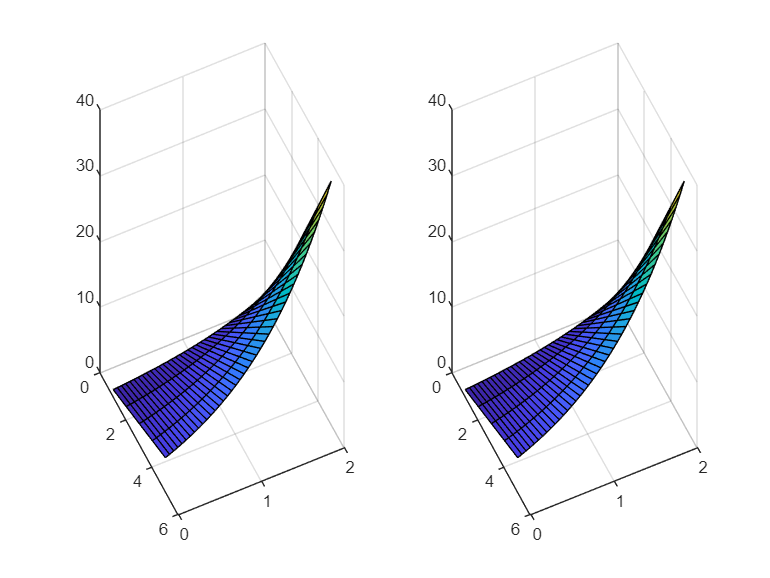

%Solucion
clear all
sol = @(x,t) t.*exp(x);
m=2;
F  = struct('l', @(x,t)  ones(size(x)), ...
    'u', @(x,t)  exp(x).*(-t.^2+t-1)-t.^(m-1).*exp(m.*x), ...
    'v', @(x,t)  (ones(size(x)))./t, ...
    'w', @(x,t)  ones(size(x))*t, ...
    'm', 2);
bi = struct('blk_a', false, 'a', 0, 'ya', @(t) 0,          'ha', 1, ...
    'blk_b', true, 'b', 2, 'yb', @(t) t*exp(2), 'hb', 2, ...
    't0', 1,...
    'tf', 5, ...
    'y0', @(x) exp(x), ...
    'hx', 0.2, ...
    'dt', 1);

hx = 0.05;
nx = (bi.b-bi.a)/hx;
x  =  bi.a  +  hx*(0:nx);
nl = struct('yk', exp(x), 'maxit', 1500, 'tol', 1.e-4);

nt = (bi.tf-bi.t0)/bi.dt;

% check(F,bi,hx,dt)

[x, t, Y] = dfnle_esquema(F, bi, nx, nt, nl, @dfn);

clf
tiledlayout(1,2)
nexttile
surf(t,x,transpose(Y))
view([64.7 30.8])
hold on
clear Z
for i=1:length(x)
    for j=1:length(t)
        Z(i,j)=sol(x(i),t(j));
    end
end
nexttile
surf(t,x,Z)
view([64.7 30.8])

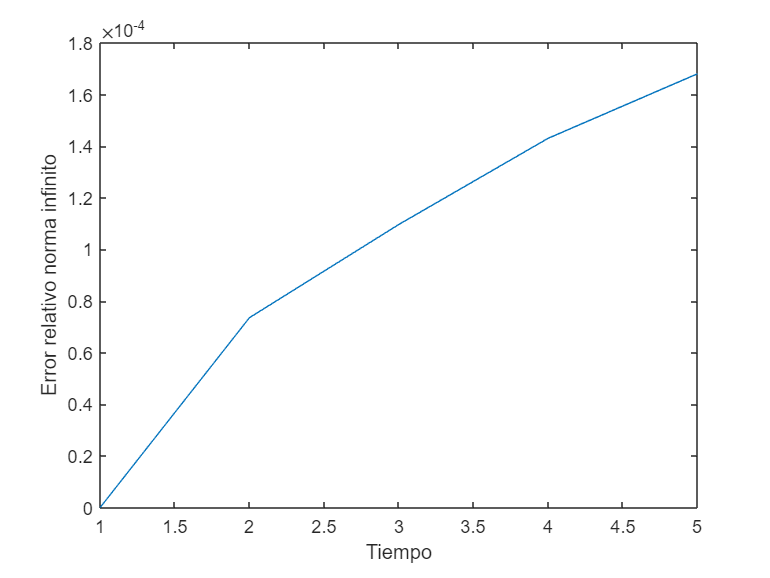

tiledlayout('flow')
ErrRel = abs(Z-transpose(Y))./Z;

nexttile
plot(t,max(ErrRel))
xlabel('Tiempo')
ylabel('Error relativo norma infinito')

### Ejercicio 4.6. Balance de masa de un reactor no lineal para Newton

Considera el problema del Ejercicio 4.4.

- **Resuelve el problema no lineal con **$m=2$ **mediante diferencias finitas.** 

%Solucion
L = 10; D = 1; U = 1; gm = 0.2; cin = 100;
m = 2;
F  = struct('l', @(x,t)  1/D.*ones(size(x)), ...
    'u', @(x,t)   zeros(size(x)), ...
    'v', @(x,t) gm*(ones(size(x))).^m/D, ...
    'w', @(x,t)  U*ones(size(x))/D, ...
    'm', m);
bi = struct('blk_a', false, 'a', 0, 'ya', @(t) U/D,          'ha', U/D, ...
    'blk_b', false, 'b', L, 'yb', @(t) 0, 'hb', 0, ...
    't0', 0,...
    'tf', 25, ...
    'y0', @(x) 0, ...
    'hx', 0.25, ...
    'dt', 0.25);

nx = (bi.b-bi.a)/bi.hx;
nt = (bi.tf-bi.t0)/bi.dt;

nl = struct('yk', ones(1,nx+1), 'maxit', 100, 'tol', 1.e-6);


check(F,bi)

Cumple la estabilidad de la discretización. Retirar punto y coma para saber el DeltaT máximo.


ans = 0.0313

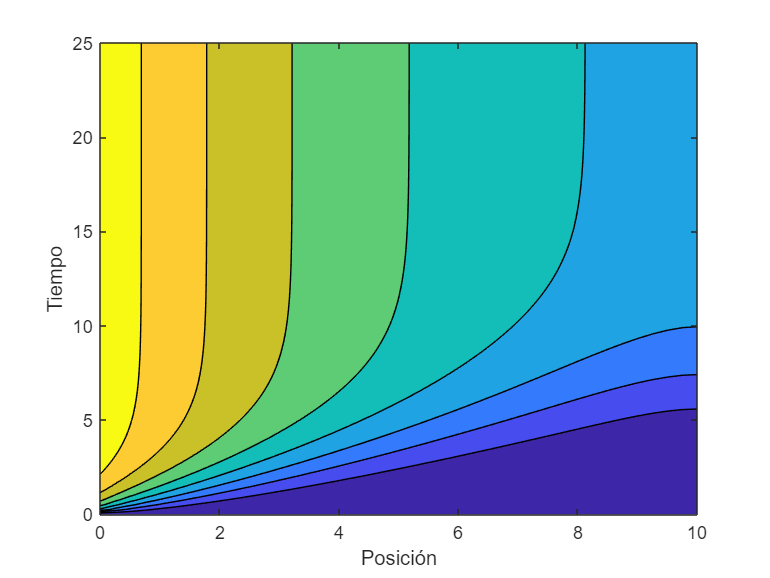

[x, t, Y] = dfnle_esquema(F, bi, nx, nt, nl, @dfn);

clf
contourf(x,t,Y)
ylabel('Tiempo')
xlabel('Posición')

## **Anexo. Funciones utilizadas en esta práctica**

En Matlab, las funciones utilizadas en un *script*, van al final de éste.

function deltat = check(F,bi)
xx  =  bi.a:bi.hx:bi.b;
tt  =  bi.t0:bi.dt:bi.tf;

for i=1:length(xx)
    for j=1:length(tt)
        W(i,j) = F.w(xx(i),tt(j));
        V(i,j) = F.u(xx(i),tt(j));
        L(i,j) = F.l(xx(i),tt(j));
    end
end

Mw = max(max(W));
Mv = max(max(V));
ml = max(max(L));

deltat = ml.*bi.hx.^2./(2+Mv.*bi.hx.^2);

if (bi.hx <= 2./Mw) && (bi.dt <= ml./(Mv+2./bi.hx*bi.hx))
    disp(['Cumple la estabilidad de la discretización. Retirar punto y coma para saber el DeltaT máximo.'])
else
    disp(['No cumple la estabilidad de la discretización.'])
end

end

function [nL2, nH1] = normaInft(xh, th, Y, sol)
%NORMAINFT   Calculo de las normas Loo(L2) y Loo(H1) discretas del error absoluto.
%Nota: trapz(..., 2) integra a lo largo de las columnas (dimension 2)
clear Z Y1e
for i=1:length(xh)
    for j=1:length(th)
        Z(i,j)=sol(xh(i),th(j));
    end
end

err = abs(transpose(Y)-Z);

nL2 = max(sqrt(trapz(xh,err.^2,1)));

%NORMAH1   Calculo de la norma H1 discreta del error absoluto.
h=(xh(end)-xh(1))/length(xh);

syms x t
sol = t.*exp(x);
dsol = matlabFunction(diff(sol,x));

for i=1:(length(xh)-2)
    for j=1:length(th)
        Y1e(i,j)=dsol(th(j),xh(i));
    end
end

%Aproximadas
d1 = @(Y,h) (Y(:,3:end)-Y(:,1:end-2))./(2.*h);            %aprox. primera derivada
Y1a = d1(Y,h);

%Errores
err1=abs(transpose(Y1a)-Y1e);

%Norma H1
nH1 = max(sqrt(trapz(xh,err.^2,1)+trapz(xh(2:end-1),err1.^2,1)));

%Gráficas
tiledlayout(1,2)
nexttile
surf(th,xh(2:end-1),transpose(Y1a))
title('derivada aproximada')
view([64.7 30.8])
hold on
nexttile
surf(th,xh(2:end-1),Y1e)
title('derivada exacta')
view([64.7 30.8])

end

function residuo(h, maxdt)
%RESIDUO   Representacion grafica del residuo.

% No me he visto en la necesidad de utilizarlo.

end